# 4-4-2016 - This is a exploratory script to try and summarize the major Beta Stim findings thus far, and to get ready for a site visit poster 

Beta Recording Channels for each subject

7dbdec - 4

d5cd55 - 53

c91479 - 64

9ab7ab - 51

702d24 - 5 

ecb43e - 55

0b5a2e - 31 

Idea is to load in the stats 

## Structure of dataForAnova

a = 1e6*max(abs((awins(t>0.01 & t < 0.030,keeps))));

dataForAnova{chan}{typei} = {a label keeps};

the baseline pulses are : a(label(keeps)==0)

similarly, 1-2 is a(label(keeps)==1), 3-4 is a(label(keeps))

chan is the channel, typei is positive peak, negative peak, etc. keeps 

Start with 0b5a2e 

close all;clear all;clc
sid = '0b5a2e'

sid = 0b5a2e


SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));
load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2eepSTATSsig'))
load tTemp.mat

betaChan = 31;

type1 = cell2mat([CCEPbyNumStim{betaChan}{1}{1:3}]);
type2 = cell2mat([CCEPbyNumStim{betaChan}{2}{1:3}]);
BigAveResp(betaChan) = (type1(14)+type2(14))/2;
latencyResp(betaChan) = (type1(15)+type2(15))/2;

% data for anova
temp = dataForAnova{31}

temp =     {1x3 cell}    {1x3 cell}    {1x3 cell}


temp23 = dataForAnova{23}

temp23 =     {1x3 cell}    {1x3 cell}    {1x3 cell}



a = [dataForAnova{23}{1:end}]

a =     [1x305 double]    [1x1290 double]    [1x1290 logical]    [1x331 double]    [1x1290 double]    [1x1290 logical]    [1x323 double]    [1x1290 double]    [1x1290 logical]



numTypes = length(dataForAnova{betaChan})

numTypes = 3


avgResp5Great =[]

avgResp5Great = []

avgRespBase = []

avgRespBase = []

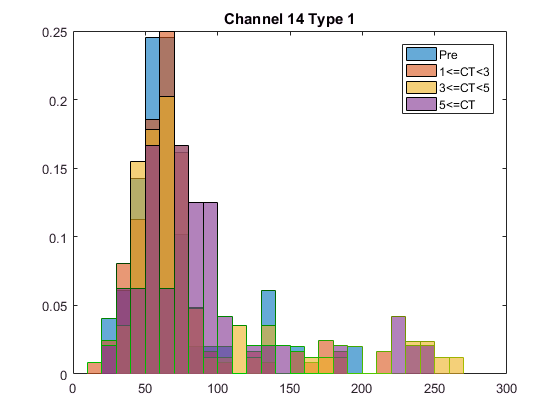

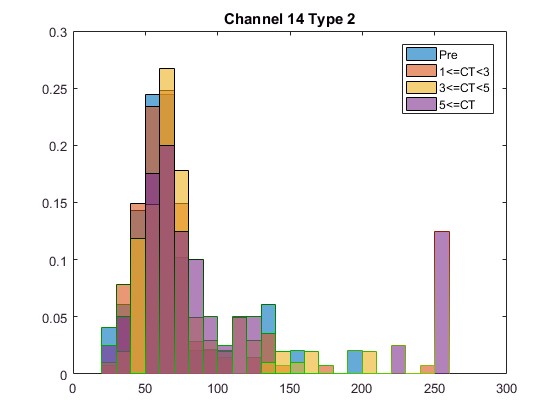

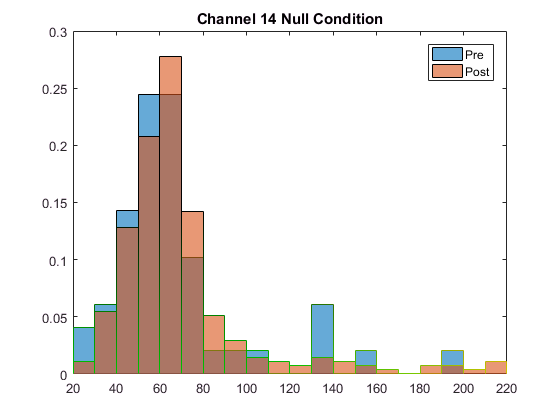

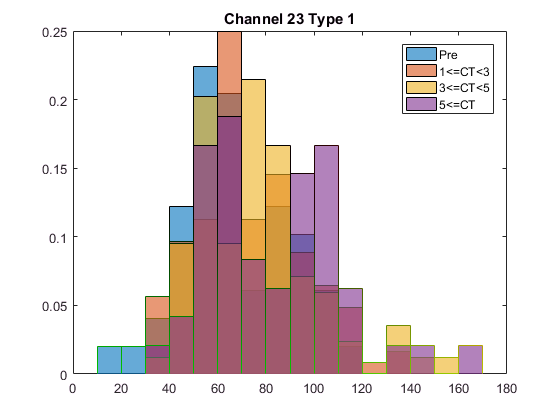

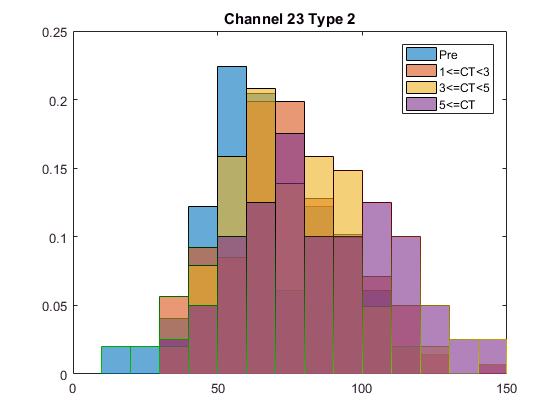

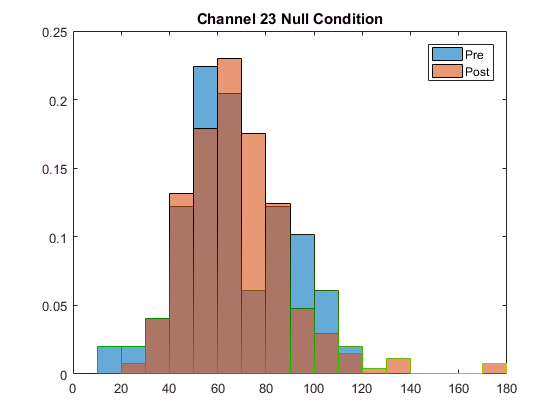

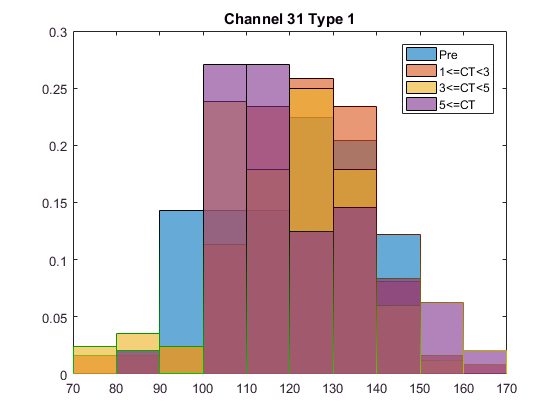

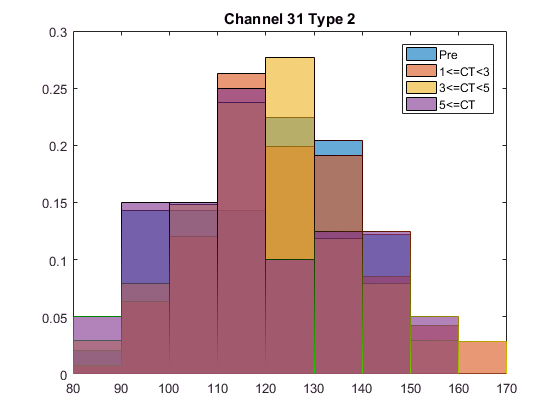


nullType = 3;

betaChan = 23;

chanList = [14 23 31];

for chan = chanList
    for i = 1:numTypes
        
        if i ~= nullType
            tempMag = dataForAnova{chan}{i}{1};
            tempLabel = dataForAnova{chan}{i}{2};
            tempKeeps = dataForAnova{chan}{i}{3};
            
            tempBase = tempMag(tempLabel(tempKeeps)==0);
            tempResp1 = tempMag(tempLabel(tempKeeps)==1);
            tempResp2 = tempMag(tempLabel(tempKeeps)==2);
            tempResp3 = tempMag(tempLabel(tempKeeps)==3);
            
            figure
            h1 = histogram(tempBase);
            hold on
            h2 = histogram(tempResp1);
            h3 = histogram(tempResp2);
            h4 = histogram(tempResp3);
            
            h1.BinWidth = 10;
            h2.BinWidth = 10;
            h3.BinWidth = 10;
            h4.BinWidth = 10;
            
            h1.Normalization = 'probability';
            h2.Normalization = 'probability';
            h3.Normalization = 'probability';
            h4.Normalization = 'probability';
            
            
            
            
            labelGroupStarts = [1 3 5];
            labelGroupEnds   = [labelGroupStarts(2:end) Inf];
            
            leg = {'Pre'};
            for d = 1:length(labelGroupStarts)
                if d == length(labelGroupStarts)
                    leg{end+1} = sprintf('%d<=CT', labelGroupStarts(d));
                else
                    leg{end+1} = sprintf('%d<=CT<%d', labelGroupStarts(d), labelGroupEnds(d));
                end
            end
            legend(leg)
            title(['Channel ',num2str(chan),' Type ', num2str(i)])
                        xlabel('CCEP Magnitude in mV')

        elseif i == nullType
            tempMag = dataForAnova{chan}{i}{1};
            tempLabel = dataForAnova{chan}{i}{2};
            tempKeeps = dataForAnova{chan}{i}{3};
            
            tempBase = tempMag(tempLabel(tempKeeps)==0);
            tempResp1 = tempMag(tempLabel(tempKeeps)==1);
            
            figure
            h1 = histogram(tempBase);
            hold on
            h2 = histogram(tempResp1);
            
            leg = {'Pre','Post'};
            
            legend(leg)
            title(['Channel ',num2str(chan), ' Null Condition'])
            
            h1.BinWidth = 10;
            h2.BinWidth = 10;
            
            
            h1.Normalization = 'probability';
            h2.Normalization = 'probability';
            
                        xlabel('CCEP Magnitude in mV')

        end
        
    end
end

# Ok - let's think about just >=5 and baseline for ease of comparison 

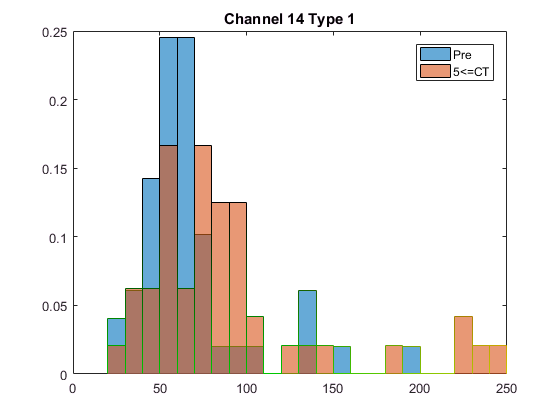

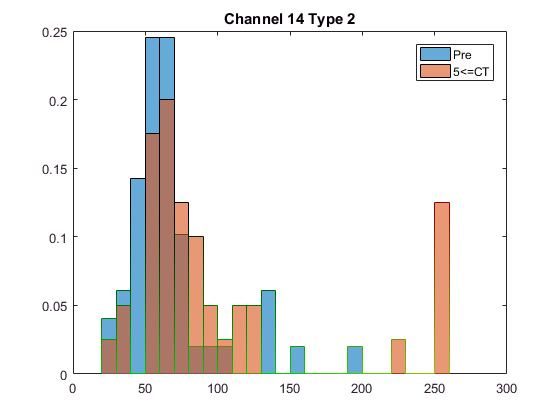

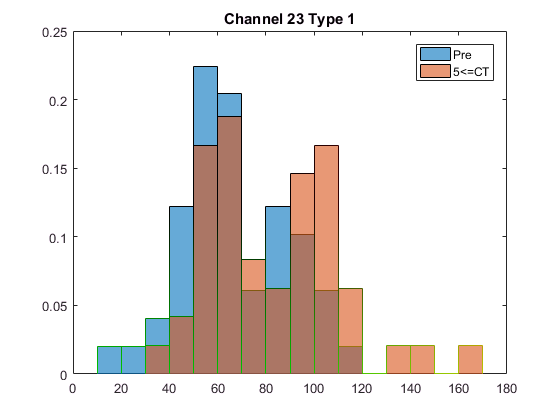

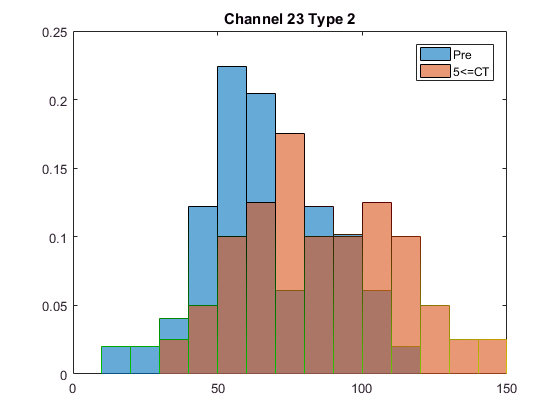

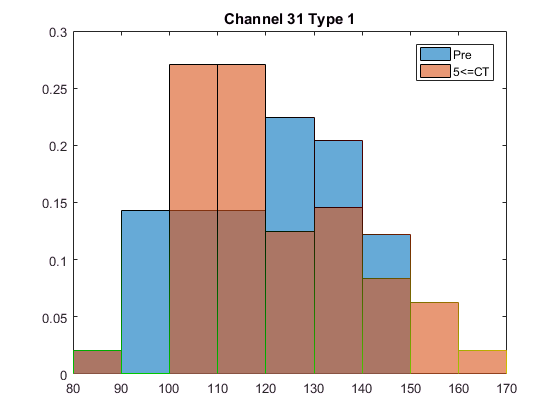

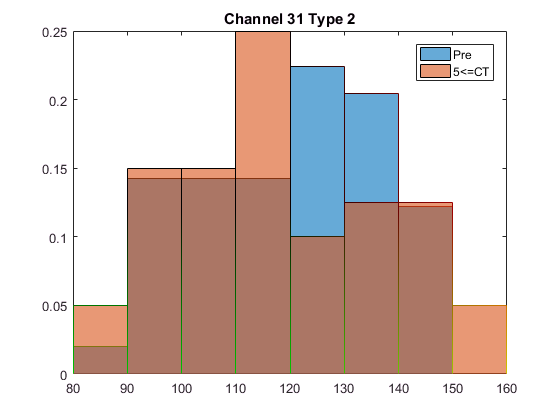

for chan = chanList
    for i = 1:numTypes
        
        if i ~= nullType
            tempMag = dataForAnova{chan}{i}{1};
            tempLabel = dataForAnova{chan}{i}{2};
            tempKeeps = dataForAnova{chan}{i}{3};
            
            tempBase = tempMag(tempLabel(tempKeeps)==0);
            
            tempResp3 = tempMag(tempLabel(tempKeeps)==3);
            
            figure
            h1 = histogram(tempBase);
            hold on
            
            h4 = histogram(tempResp3);
            
            h1.BinWidth = 10;
            
            h4.BinWidth = 10;
            
            h1.Normalization = 'probability';
            
            h4.Normalization = 'probability';
            
            
            
            
            labelGroupStarts = [1 3 5];
            labelGroupEnds   = [labelGroupStarts(2:end) Inf];
            
            leg = {'Pre'};
            
            leg{end+1} = sprintf('%d<=CT', labelGroupStarts(d));
            
            
            legend(leg)
            title(['Channel ',num2str(chan),' Type ', num2str(i)])
            
            xlabel('CCEP Magnitude in mV')
            
        elseif i == nullType
            tempMag = dataForAnova{chan}{i}{1};
            tempLabel = dataForAnova{chan}{i}{2};
            tempKeeps = dataForAnova{chan}{i}{3};
            
            tempBase = tempMag(tempLabel(tempKeeps)==0);
            tempResp1 = tempMag(tempLabel(tempKeeps)==1);
            
            figure
            h1 = histogram(tempBase);
            hold on
            h2 = histogram(tempResp1);
            
            leg = {'Pre','Post'};
            
            legend(leg)
            title(['Channel ',num2str(chan),' Null Condition'])
            
            h1.BinWidth = 10;
            h2.BinWidth = 10;
            
            
            h1.Normalization = 'probability';
            h2.Normalization = 'probability';
                        xlabel('CCEP Magnitude in mV')

            
        end
        
    end
end